# Training Unit 5: ODE numerical solver

Fink Lucas / Teichtmeister Marcus, 28.10.2025

## MATLAB Setup

clear
clc

Set LaTex interpreter as default for graphics

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Set font size for graphics

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Change directory (into the live script directory)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Derivation of the Analytical Solution of the Ordinary Differential Equation

The following ODE is given:


$$\frac{\textrm{dy}}{\textrm{dt}}=-\frac{y}{\tau \;}$$


First, the equation is multiplied by $\textrm{dt}$ and divided by $y$.


$$\frac{1}{y}\textrm{dy}=-\frac{1}{\tau \;}\textrm{dt}$$


Then integrated on both sides.


$$\int \;\frac{1}{y}\textrm{dy}=-\int \;\frac{1}{\tau \;}\textrm{dt}\to \ln \left(|y|\right)+C_1 =-\frac{t}{\tau \;}+C_2 \to \ln \left(|y|\right)=-\frac{t}{\tau \;}+C$$



$$y=e^{-\frac{t}{\tau \;}+C} =e^C e^{-\frac{t}{\tau \;}}$$


Which gives the function:


$$y=y_0 \;e^{-\frac{t}{\tau \;}}$$
    

## Implementing the analytical solution

PARAMETERS.y_0     = 1

PARAMETERS = struct with fields:
        y_0: 1
        t_0: 0
    t_final: 10
          h: 1
        tau: 2
          N: 10


PARAMETERS.t_0     = 0

PARAMETERS = struct with fields:
        y_0: 1
        t_0: 0
    t_final: 10
          h: 1
        tau: 2
          N: 10


PARAMETERS.t_final = 10

PARAMETERS = struct with fields:
        y_0: 1
        t_0: 0
    t_final: 10
          h: 1
        tau: 2
          N: 10


PARAMETERS.h       = 1

PARAMETERS = struct with fields:
        y_0: 1
        t_0: 0
    t_final: 10
          h: 1
        tau: 2
          N: 10


PARAMETERS.tau     = 2

PARAMETERS = struct with fields:
        y_0: 1
        t_0: 0
    t_final: 10
          h: 1
        tau: 2
          N: 10


PARAMETERS.N        = 10

PARAMETERS = struct with fields:
        y_0: 1
        t_0: 0
    t_final: 10
          h: 1
        tau: 2
          N: 10


## Implementing the Numerical Solution

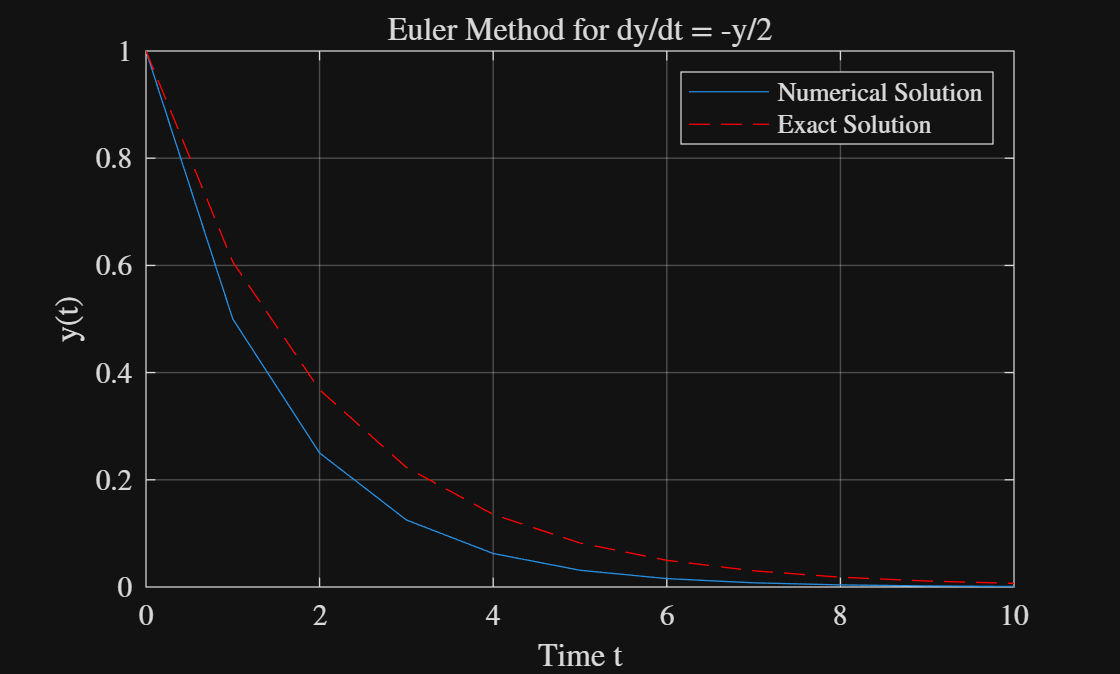

% Initialize vectors
y_num = zeros(1, PARAMETERS.N+1);
t = PARAMETERS.t_0:PARAMETERS.h:PARAMETERS.t_final;

% Initial condition
y_num(1) = PARAMETERS.y_0;

% Euler method for dy/dt = -y/2
for n = 1:PARAMETERS.N
    y_num(n+1) = y_num(n) + PARAMETERS.h * (-y_num(n)/PARAMETERS.tau);
end

% Analytical solution
y_exact = PARAMETERS.y_0 * exp(-t/PARAMETERS.tau);

% Plot
figure;
plot(t, y_num);
hold on;
plot(t, y_exact, 'r--');
grid on;
xlabel('Time t');
ylabel('y(t)');
title('Euler Method for dy/dt = -y/2');
legend('Numerical Solution', 'Exact Solution', 'Location', 'northeast');